% PROBLEMA Nº 1 y 2
% Las propiedades de masa y rigidez del edificio de 3 pisos son mostradas en la Figura 1. 
% Determinar mediante el método de descomposición modal: 

% 1) Las frecuencias y modos de vibración (resuelva a mano y verifique con Matlab). 
% 2) Si a la estructura se le impone los siguientes desplazamientos iniciales: 
% x1(0) = 0.3in, x2(0) = -0.8in, x3(0) = 0.3in,
% determine los desplazamientos en el instante de tiempo t=2?/?1.
% Admitiendo una relación de amortiguamiento crítico de 0% y de 10% en cada modo.
clc
clear
%--------Datos del problema-------
m = [2,2,2];
k  = [600,1200,2400];
H = 0.5;  %Altura entre masas
Xo = [0.3;-0.8;0.3];
Xop = [0;0;0];
Tp = 2*pi;
N = 1000;
wf = (2*pi)/Tp;
dseta = 0.1;
Vibraciones = 'Forzadas'    %'Libres' o 'Forzadas'

Vibraciones = 'Forzadas'

Carga = 'Senoidal'        %'Senoidal', 'Cosenoidal' o 'Exponencial'

Carga = 'Senoidal'


%------Matrices y vectores auxiliares----
phi = zeros(length(m),length(m));
M = zeros(length(m), length(m));
K = zeros(length(k),length(k));
y = linspace(0 , H*length(m), length(m)+1);
t = linspace(0 , 2*pi , N);
I = eye(length(m));
vector_ceros = zeros(1,3);

%-------Matrices-------
M = diag(m)

M =      2     0     0
     0     2     0
     0     0     2


K = [k(1) -k(1) 0; -k(1) k(1)+k(2) -k(2); 0 -k(2) k(2)+k(3)]

K =          600        -600           0
        -600        1800       -1200
           0       -1200        3600



%---------Autovectores y Autovalores--------
[AutoV,lamda] = (eig(K,M))         %Calculo Autovectores normalizados con respecto a la masa

AutoV =     0.6111    0.3516    0.0537
    0.3346   -0.5322   -0.3238
    0.1206   -0.3053    0.6263


lamda = 	1.0e+03 *

    0.1357         0         0
         0    0.7540         0
         0         0    2.1102


Wn = diag(lamda.^0.5)              %Saco frecuencias naturales de cada elemento

Wn =    11.6511
   27.4598
   45.9370




%------Saco el phi normalizado a si mismo para ver los modos---------
for i = 1:length(AutoV(:,1))
  phi(:,i) = AutoV(:,i)/AutoV(1,i);
end

AutoVT = transpose(AutoV);    %Transpuesta del autovector
Mn = AutoVT*M*AutoV;          %Normalizacion  de la matriz masa
Kn = AutoVT*K*AutoV          %Normalizacion de la matriz de rigideces

Kn = 	1.0e+03 *

    0.1357   -0.0000    0.0000
   -0.0000    0.7540   -0.0000
    0.0000    0.0000    2.1102


Cn = 2*dseta*(lamda.^0.5)

Cn =     2.3302         0         0
         0    5.4920         0
         0         0    9.1874


Xon = Mn/I*AutoVT*M*Xo; %No se por que se normaliza de esta forma
Xopn = Mn/I*AutoVT*M*Xop;

switch Vibraciones
  case 'Forzadas'                             %Si son forzadas, cambiar el 1.1*Wn(1). P0 y la posicion de P0 dependiendo el ejercicio,
    P0 = 5000;
    Pon = AutoVT*[P0;0;0]
    switch Carga
      case 'Senoidal'
        for i = 1:length(m)
          beta(i) = (1.1*Wn(1))/Wn(i);
          D(i) = 1/(((1-beta(i)^2)^2)+(2*dseta*beta(i))^2)^0.5;
          rho(i) = (Pon(i)/Kn(i,i))*D(i);
          desfasaje(i) = atan((2*dseta*beta(i))/(1-beta(i)^2));
          for j = 1: length(t)
            Xn(i,j) = rho(i)*sin(1.1*Wn(1)*t(j)-desfasaje(i));
          end
        end
        X = AutoV*Xn;
        
      case 'Cosenoidal'
        for i = 1:length(m)
          beta(i) = (1.1*Wn(1))/Wn(i);
          D(i) = 1/(((1-beta(i)^2)^2)+(2*dseta*beta(i))^2)^0.5;
          rho(i) = (Pon(i)/Kn(i,i))*D(i);
          desfasaje(i) = atan((2*dseta*beta(i))/(1-beta(i)^2));
          for j = 1: length(t)
            Xn(i,j) = rho(i)*cos(1.1*Wn(1)*t(j)-desfasaje(i));
          end
        end
        X = AutoV*Xn;
        
      case 'Exponencial'
        for i = 1:length(m)
            beta(i) = (1.1*Wn(1))/Wn(i);
            D(i) = 1/(((1-beta(i)^2)^2)+(2*dseta*beta(i))^2)^0.5;
            rho(i) = (Pon(i)/Kn(i,i))*D(i);
            desfasaje(i) = atan((2*dseta*beta(i))/(1-beta(i)^2));
          for j = 1: length(t)
            Xn(i,j) = rho(i)*exp(1.1*Wn(1)*t(j)-desfasaje(i));
          end
        end
        X = AutoV*Xn;
    end
    
    
  case 'Libres'
    for i = 1:length(m)
      for j = 1:length(t)
        Xn(i,j) = (exp(-dseta*Wn(i)*t(j)))*(Xon(i)*cos(((1-dseta^2)^0.5)*Wn(i)*t(j))+((Xopn(i)+dseta*Wn(i)*Xon(i))/(Wn(i)*(1-dseta^2)^0.5))*sin(((1-dseta^2)^0.5)*Wn(i)*t(j)));
      end
    end
    X = AutoV*Xn;
end

Pon = 	1.0e+03 *

    3.0557
    1.7581
    0.2683


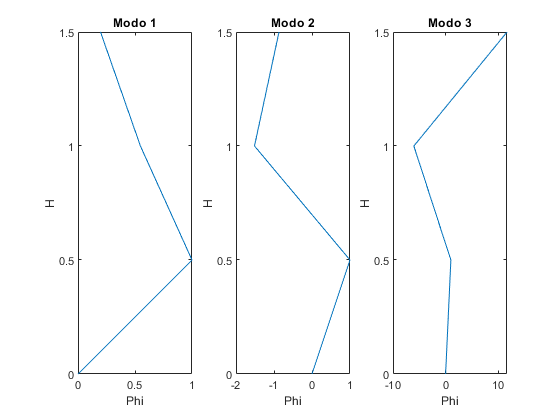

%--------Grafico los modos normalizados-------

phi = [vector_ceros; phi];    %Agrego fila de ceros a la matriz de phi para que tenga en cuenta la parte fija

figure(1);
subplot(1,3,1);
plot(phi(:,1),y);
xlabel('Phi');
ylabel('H');
title('Modo 1');

subplot(1,3,2);
plot(phi(:,2),y);
xlabel('Phi');
ylabel('H');
title('Modo 2');

subplot(1,3,3);
plot(phi(:,3),y);
xlabel('Phi');
ylabel('H');
title('Modo 3');

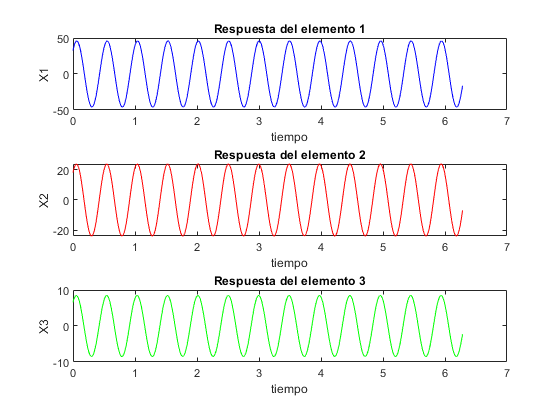



%--------Grafico respuestas de las diferentes masas-------

t0 = 0;
tf = 10;
[tode,yw]= ode45(@(tode,yw) [yw(4:6); -inv(Mn)*(Kn*yw(1:3)+Cn*yw(4:6))], [t0 tf], [Xon; Xopn]);
xw= AutoV*yw(:, 1:3)';

figure(2);

subplot(3,1,1);
plot(t,X(1,:), 'b')%,tode,xw(1,:), 'k');
xlabel('tiempo');
ylabel('X1');
title('Respuesta del elemento 1');

subplot(3,1,2);
plot(t,X(2,:), 'r');%,tode,xw(2,:), 'k');
xlabel('tiempo');
ylabel('X2');
title('Respuesta del elemento 2');

subplot(3,1,3);
plot(t,X(3,:), 'g');%,tode,xw(3,:), 'k');
xlabel('tiempo');
ylabel('X3');
title('Respuesta del elemento 3');